clc; clear; close all;

# Error analysis of 1D-FC using Barycentric Interpolation

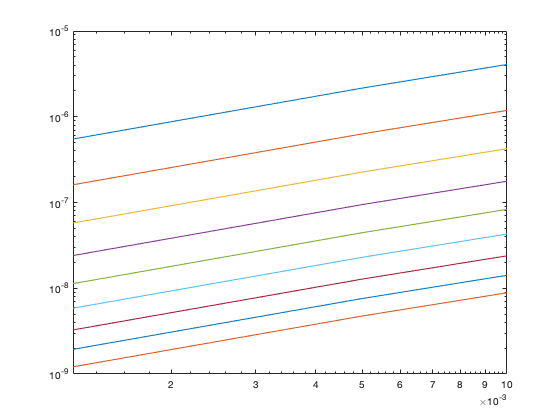

% fixed data
k_lst = [0.01, 0.005, 0.00125];
d_lst = 4:12;
C = 27;
L = 1;

phi = @(x) sin(pi*x/L); % function

% error analysis mesh
k_err = 0.00125/20;
D_err = transpose(0:k_err:L);
phi_D_err = phi(D_err);

% error table
err = zeros(length(k_lst), length(d_lst));

for i = 1:length(k_lst)
    k = k_lst(i);
    D = transpose(0:k:L); % domain
    phi_D = phi(D); % function values on domain

    for j = 1:length(d_lst)
        d = d_lst(j);
        
        D_l = D(1:d); % left side of mesh on domain of function
        D_r = D(end-d+1:end); % right side of mesh on domain of function
        phi_D_l = phi(D_l); % phi values on left side of mesh
        phi_D_r = phi(D_r); % phi values on right side of mesh
        
        D_C = transpose(L+k:k:L+C*k); % vector of only continuation points domain
        D_l_C = D_l + D_C(end) + k; % left side of mesh of next periods domain after continuation, has values of phi_D_l
        
        D_interpolant = [D_r;D_l_C]; % mesh used for interpolation
        phi_interpolant = [phi_D_r; phi_D_l]; % function values used for interpolation
        w = barycentric_weights([D_r;D_l_C]); % barycentric weights dependent on interpolation mesh
        phi_C = barycentric_compute_func(w, D_interpolant, phi_interpolant, D_C); % continuation values using barycentric interpolation
        
        D_FC = [D; D_C]; % final continued domain
        phi_FC = [phi_D; phi_C]; % final continued function values
        
        % FFT Procedure
        L_FC = D_FC(end) + k; % new period after 1D-FC
        C_n = FFT_coeff(phi_FC); % ceofficients given by FFT
        
        % Error Calculation
        phi_FFT = FFT_compute_func(C_n, L_FC, D_err);
        error(i, j) = max(abs(phi_FFT - phi_D_err));
    end
end

figure;
loglog(k_lst, error)

error

ans =      9.141387856077759e-01


error =      4.071547850712301e-06     1.185556062453796e-06     4.243506014182941e-07     1.770232149894690e-07     8.313587841410341e-08     4.289466294486732e-08     2.388880684239814e-08     1.416962897016205e-08     8.860693082035631e-09
     2.160609834362878e-06     6.316061120234875e-07     2.265489660452369e-07     9.463268291036442e-08     4.447330131766847e-08     2.296715553243983e-08     1.279471203031318e-08     7.593856395267384e-09     4.748985584120125e-09
     5.495866265093838e-07     1.609530747527163e-07     5.771180349844335e-08     2.406723256364457e-08     1.132371768401697e-08     5.856121891231747e-09     3.265947621719500e-09     1.938680547694527e-09     1.212323628638212e-09
